# Sprawozadanie

# z Laboratorium Metod numerycznych

## Ćwiczenie 2:

## Numeryczne zagadnienia algebry liniowej

Autor: Dominik Gajda, 240661

        Maksym Dmytruk, 240353

Data wykonania ćwiczenia: 26.10.2022

Data sporządzenia i oddania sprawozdania: 01.11.2022

### Część 1. 

#### Ćwiczenia wprowadzające

Wykonano eliminację Gaussa bez wyboru elementu głównego "krok po kroku" w trybie interaktywnym. 


$$\textrm{Ax}=B$$


Wygenerowano przykładowy układ równań:

format long % ustawienie "długiego" formatu wyników, t.j. 15 cyfr po kropce dziesiętnej
format compact % wyłączenie niektóryk znaków nowej linii przy wyprowadzaniu wyników
[A,b,x0]=tstelgN(240661,4) % Tu należy wpisać jako argument swój numer indeksu

A =     -2     9   -10    -3
     4   -24    17    12
    22   -51   140   -23
   -22   117  -137   -15


b =      5
    29
  -401
   118


x0 =     -4
    -3
    -3
     2


Sprawdzenie, że rozwiązanie dostarczone przez generator jest poprawne:

A*x0-b

ans =      0
     0
     0
     0


Dla rozwiązywania układu równań wygodnie jest "zblokować" macierz układu równań z wektorem prawych stron. Współczynniki, użyte do eliminacji należy zapisywać w dodatkowej macierzy L, która na końcu będzie macierzą trójkątną dolną (z jedynkami na przekątnej - dlatego jest inicjowana macierzą jednostkową)

AB=[A,b],L=eye(4) % "Zblokowanie" macierzy układu i wektora prawych stron,

AB =     -2     9   -10    -3     5
     4   -24    17    12    29
    22   -51   140   -23  -401
   -22   117  -137   -15   118


L =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


                  % zainicjowanie zmiennej L

Pierwszy etap eliminacji

L(2:4,1)=AB(2:4,1)/AB(1,1) % Obliczenie współczynników eliminacji dla 

L =      1     0     0     0
    -2     1     0     0
   -11     0     1     0
    11     0     0     1


                           % wszystkich wierszy
AB(2:4,:)=AB(2:4,:)-L(2:4,1)*AB(1,:) % Eliminacja wyrazów 

AB =     -2     9   -10    -3     5
     0    -6    -3     6    39
     0    48    30   -56  -346
     0    18   -27    18    63


                                     %  poddiagonalnych w pierwszej kolumnie

Drugi etap eliminacji 

L(3:4,2)=AB(3:4,2)/AB(2,2)    % Obliczenie współczynników

L =      1     0     0     0
    -2     1     0     0
   -11    -8     1     0
    11    -3     0     1


AB(3:4,:)=AB(3:4,:)-L(3:4,2)*AB(2,:)    % Eliminacja wyrazów poddiagonalnych 

AB =     -2     9   -10    -3     5
     0    -6    -3     6    39
     0     0     6    -8   -34
     0     0   -36    36   180


                                        % w drugiej kolumnie

Trzeci etap eliminacji

L(4:end,3)=AB(4:end,3)/AB(3,3)   % Obliczenie współczynników

L =      1     0     0     0
    -2     1     0     0
   -11    -8     1     0
    11    -3    -6     1


AB(4:end,:)=AB(4:end,:)-L(4:end,3)*AB(3,:)     % Eliminacja wyrazów poddiagonalnych 

AB =     -2     9   -10    -3     5
     0    -6    -3     6    39
     0     0     6    -8   -34
     0     0     0   -12   -24


% w trzeciej kolumnie

Układ równań został sprowadzony do postaci trójkątnej (górnej). Aby dokończyć rozwiązywanie układu równań, trzeba wykonać **podstawienie wstecz.**

Inicjujemy zmienną przeznaczoną na rozwiązanie:

x=nan(size(b))

x =    NaN
   NaN
   NaN
   NaN


Obliczenie ostatniej niewiadomej

x(4)=AB(4,5)/AB(4,4)

x =    NaN
   NaN
   NaN
     2


Obliczenie trzeciej niewiadomej

x(3)=(AB(3,5)-AB(3,4)*x(4))/AB(3,3)

x =    NaN
   NaN
    -3
     2


Obliczenie drugiej niewiadomej (uzupełnić)

x(2)= (AB(2,5)-AB(2,4)*x(4)-AB(2,3)*x(3))/AB(2,2)

x =    NaN
    -3
    -3
     2


Obliczenie pierwszej niewiadomej (uzupełnić)

x(1)= (AB(1,5)-AB(1,4)*x(4)-AB(1,3)*x(3)-AB(1,2)*x(2))/AB(1,1)

x =     -4
    -3
    -3
     2


Sprawdzenie poprawności wyniku

A*x-b

ans =      0
     0
     0
     0


#### Funkcja do eliminacji Gaussa bez wyboru elementu głównego

Należy uogólnić użyty wcześniej kod, tak, aby działał dla układów n równań z n niewiadomymi. Należy tak napisać kod, aby prawa strona mogła być macierzą, a niekoniecznie wektorem.

[A,b,x0]=tstelgN(240661,7); % Należy wygenerować 
                            % większy testowy układ równań 

[x, L, U] = elgauss(A, b);


Należy skopiować kod z poprzedniej sekcji (po jego uruchomieniu) i przy pomocy opcji "Convert to local function" stworzyć funkcję lokalną o nazwie elgauss i listach parametrów wejściowych i wyjściowych jak w kolejnej sekcji. Użyć w/w nasępnej sekcji do przetestowania poprawności utworzenia funkcji.

A*x-b

ans =      0
     0
     0
     0
     0
     0
     0


L*U-A

ans =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


Uruchomienie funkcji

[A,b,x0]=tstelgN(654321,7); % Można wygenerować nowy przykład
[x, L, U]=elgauss(A, b);
A*x-b

ans =      0
     0
     0
     0
     0
     0
     0


L*U-A

ans =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


Zmodyfikować napisaną funkcję tak, by mnożniki służące do eliminacji (elementy macierzy `L`) nie były przechowywane w oddzielnej zmiennej, tylko w miejscu niepotrzebnych już ("wyzerowanych") elementów tablicy `Ab` zawierającej macierz układu i prawą stronę (poniżej głównej przekątnej).

W efekcie powinna powstać funkcja `elgauss2` o takiej samej składni wywołania, co `elgauss`.

[x, L, U] = elgauss2(A, b);
A*x-b

ans =      0
     0
     0
     0
     0
     0
     0


L*U-A

ans =    -75   119    96    -9   -25    30     0
   439    50    69  -204    20   -30   150
  -339   130  -166   438  -117   -17  -160
  -171   278    33    83   -51   138  -211
  -273   550   210  -250    90   145   -71
   126  -219  -133   155   -69    50   -38
   -85     9  -112   132   -46  -116   -32


Skopiowano przetestowany kod z poprzedniej sekcji i przekształć do funkcji `elgauss2`

Przetestuj stworzoną funkcję:

[A,b,x0]=tstelgN(654321,7); % Można wygenerować nowy przykład
x=elgauss2(A,b)

x =      5
    -7
    -6
     2
    -6
     1
    -2


b-A*x

ans =      0
     0
     0
     0
     0
     0
     0


Zapoznano się z dokumentacją funkcji max

A

A =    -14    -2     2   -14   -17    10     1
   -70    -7    21   -50   -89    30    19
   182    74   165   515   176  -463   195
  -294   -42  -108  -429  -544   326   169
  -280   -13    34  -246  -491   -29   121
  -238   -61   160  -283   233  -157  -432
  -224    -2   232    89  -309    84   106


[mx,idx]=max(abs(A(:,1)))

mx =    294

idx =      4

Przećwiczyczono operacje indeksowania pozwalające na zamianę dwóch wierszy

M=A

M =    -14    -2     2   -14   -17    10     1
   -70    -7    21   -50   -89    30    19
   182    74   165   515   176  -463   195
  -294   -42  -108  -429  -544   326   169
  -280   -13    34  -246  -491   -29   121
  -238   -61   160  -283   233  -157  -432
  -224    -2   232    89  -309    84   106


M([2,4],:)=M([4,2],:)

M =    -14    -2     2   -14   -17    10     1
  -294   -42  -108  -429  -544   326   169
   182    74   165   515   176  -463   195
   -70    -7    21   -50   -89    30    19
  -280   -13    34  -246  -491   -29   121
  -238   -61   160  -283   233  -157  -432
  -224    -2   232    89  -309    84   106


[~,idx]=max(abs(M(2:end,2)))

idx =      2

#### Eliminacja Gaussa z częściowym wyborem elementu głównego w kolumnie

Skopiowano kod eliminacji Gaussa bez wyboru elementu głównego i zmodyfikowano tak, aby wykonywany był częściowy wybór elementu głównego w kolumnie. W efekcie powinien powstać kod obliczający rozwiązanie układu równań i rozkład trójkątny macierzy z poprzestawianymi wierszami, a także macierz permutacji. [x, U, L, P] = elgwegk(A, b);

[x, U, L, P]=elgwegk(A,b);

Skopiowano do tej sekcji kod przetestowany w sekcji poprzedniej i przekształć go w funkcję `elgwegk` 

Skorygowano listy parametrów funkcji utworzonej w poprzedniej sekcji i sprawdzono jej działanie przy pomocy poniższego kodu:

[A,b,x0]=tstelgN(654321,7); % Można wygenerować nowy przykład
[x,L,U,P]=elgwegk(A, b)

x =   -4.999999988336723
  -2.999999998509828
   4.999999999509247
  -0.999999999982317
   2.000000000109955
   2.999999999902131
   2.000000000056680


L = 1.0e+02 *

   0.380000000000000  -4.120000000000000  -2.660000000000000   1.440000000000000   1.030000000000000  -6.600000000000000  -6.750000000000000
                   0   1.328947368421053   4.330000000000000   0.644736842105263  -0.134736842105263   3.565789473684211   8.768421052631579
                   0                   0  -0.253188118811881   4.220099009900991  -3.018257425742574   0.775445544554455   3.685346534653466
                   0                   0                   0   1.088947286094167   2.326895041451587   2.040603785390271  -1.330261223212887
                   0                   0                   0                   0  -1.282031532799739  -1.041040904154766   0.689483167759318
                   0                   0                   0                   0                   0   0.019374967647206   0.033464548402120
                   0                   0                   0                   0                   0                   0   0.00000121441756

U =    1.000000000000000                   0                   0                   0                   0                   0                   0
   0.684210526315789   1.000000000000000                   0                   0                   0                   0                   0
  -0.315789473684211  -0.768316831683168   1.000000000000000                   0                   0                   0                   0
   0.421052631578947   0.899009900990099  -0.344752072579384   1.000000000000000                   0                   0                   0
  -0.052631578947368  -0.215841584158416   0.060847802283748   0.365643727627397   1.000000000000000                   0                   0
  -0.421052631578947  -0.184158415841584  -0.029250743000155   0.283292442585360   0.919327438459097   1.000000000000000                   0
   0.052631578947368   0.027722772277228   0.000156421085562  -0.040703052728954  -0.128474689530871  -0.118454289322843   1.000000000000000


P =      0     0     0     0     1     0     0
     0     0     0     0     0     1     0
     0     0     0     1     0     0     0
     0     0     0     0     0     0     1
     0     0     0     0     0     0     1
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


A*x-b % Sprawdzenie poprawności rozwiązania

ans = 1.0e-12 *

   0.014210854715202
  -0.113686837721616
  -0.113686837721616
  -0.454747350886464
                   0
   0.454747350886464
                   0


x-x0 % Błąd rozwiązania

ans = 1.0e-07 *

   0.116632765667646
   0.014901724298966
  -0.004907532158427
   0.000176834102916
   0.001099551560912
  -0.000978692682452
   0.000566804381208


L*U-P*A % Sprawdzenie poprawności rozkładu

ans = 1.0e+02 *

   0.996842105263158   4.144297029702970  -0.241770686688577  -1.218371475686719  -5.200356939496661   0.799566452929188                   0
  -1.479418282548476  -0.312743095362167   1.486596771139492  -0.381269133800616   1.446871088408458   3.477132389411285   4.618421052631579
   2.003155810317874   4.319268150181355   0.826163777522753  -0.083834878102297   0.461157188543918   0.218900439883678   4.605346534653465
  -0.753179382054385   0.604060790499511  -3.153727642189589   1.751995186272090   0.693782990031594  -0.001821066800311  -3.770261223212887
   0.382096943884062   1.027546545564743  -2.907449731583672  -1.611749878891071  -6.007670136462123  -3.322713142791758  -1.750516832240682
  -0.006396589093449  -0.002640333294179  -0.000561497638296   0.004126672631627   0.013512591911081   0.015410948348723   0.033464548402120
   0.000000063916714   0.000000033667022   0.000000000189961  -0.000000049430502  -0.000000156021920  -0.000000143852970   0.000001214417

Na skutek występowania błędów zaokrągleń, możemy zaobserwować wyniki różne od zera.

Generator przykładów tstelgN jest tak napisany, że domyślnie dostarcza przykładów, w których brak wyboru elementu głównego prowadzi do dokładniejszych wyników. Spróbuj wywoływać ten sam generator z drugim argumentem ujemnym i porównaj błędy rozwiązania w tym przypadku.

[A,b,x0]=tstelgN(654321,-10)

A =           -7        -105        -133         203        -210           7         -77        -119         182          14
         -27        -423        -531         891        -414         423        -225        -405         468          18
         -19        -313        -385         835         -14         647        -209        -291         150         -66
          15         236         322         276         -90         304       -1159          91        -370         -44
          16         220         257       -1132        1296         436        1078         611        -738         192
         -14        -228        -256        1311        -486        -214        -356        -563         477        -440
           0         -16         -45        -729         821        1279         548         443         175        1412
           9         146         164        -850         306        -575         862         643           8         664
           1         -10    

b =        -1743
       -4365
       -1967
       -9240
       12136
        -826
      -12158
        4660
        3637
      -22901


x0 =      5
    -5
    -7
     1
     5
    -6
     6
     5
    -6
    -9


elgauss2(A,b)-x0

ans = 1.0e-04 *

  -0.776995877913578
  -0.183366652084516
   0.175545380329822
  -0.005495425601243
   0.001095121051620
   0.000048781503281
  -0.000003722675501
   0.000000141495704
   0.000000008268941
   0.000000000284217


elgwegk(A,b)-x0

ans =   -0.163965072930686
  -0.038694836867365
   0.037044357124270
  -0.001159668859521
   0.000231097232779
   0.000010294083928
  -0.000000785579497
   0.000000029861922
   0.000000001746356
   0.000000000059345


A\b-x0

ans =   -0.163965084770227
  -0.038694839661695
   0.037044359799376
  -0.001159668943256
   0.000231097249464
   0.000010294084673
  -0.000000785579546
   0.000000029861922
   0.000000001746356
   0.000000000059345


Metoda eliminacji Gaussa bez przestawiania wierszy dostarcza dokładniejszych wyników od metody z częściowym wyborem elementu głównego w kolumnie oraz od operatora dzielenia macierzy, ponieważ wynik pozostałych metod zawiera błąd rzędu e-13 dla macierzy 4x4. Wraz ze wzrostem wielkości macierzy, dla danego generatora przykładów, błąd dla funkcji `elgauss2` jest wciąż najmniejszy.

Porównano błąd rozwiązań uzyskanych przy pomocy eliminacji gaussa bez wyboru i z częściowym wyborem elementu głównego dla przykładów wygenerowanych przez funkcję `tstcndS.` Jej trzeci argument to przybliżona liczba uwarunkowania macierzy

[A,b,x0]=tstcndS(654321,20,10);
cond(A) % Sprawdzenie liczby uwarunkowania macierzy

ans =    9.999999999999998

norm(elgauss2(A,b)-x0) % Norma błędu rozwiązania bez wyboru elementu głównego

ans =      1.082574936035485e-12

norm(elgwegk(A,b)-x0) % Norma rozwiązania z wyborem elementu głównego

ans =      5.136290570329300e-14

norm(A\b-x0) % Norma rozwiązania przez wbudowany operator Matlab-a

ans =      3.375443180046173e-14

Błąd rozwiązań osiąga najmniejszą wartość dla wbudowanego operatora Matlab-a. Wraz ze wzrostem wielkości macierzy, błąd ten pozostaje najmniejszy i staje się o ponad rząd wielkości mniejszy od funkcji `elgauss2`.

[Am,bm,x0m]=tstcndS(654321,10,1e10);
cond(Am) % Sprawdzenie liczby uwarunkowania macierzy

ans =      1.001150197134363e+10

norm(elgauss2(Am,bm)-x0m) % Norma błędu rozwiązania bez wyboru elementu głównego

ans =      1.999087898342973e-07

norm(elgwegk(Am,bm)-x0m) % Norma rozwiązania z wyborem elementu głównego

ans =      8.899291653550927e-07

norm(Am\bm-x0m) % Norma rozwiązania przez wbudowany operator Matlab-a

ans =      8.899291648511292e-07

Dla bardzo wysokiego współczynnika uwarunkowania macierzy, najmniejszym błędem charakteryzuje się funkcja `elgauss2`, podczas gdy wbudowany operator osiąga bardzo zbliżony wynik do funkcji `elgwegk.`

cond(Am)

ans =      1.001211604299074e+10

### Część 2.

#### Liczba uwarunkowania macierzy a wpływ zaburzeń na błąd rozwiązania

Wskaźnik (liczba) uwarunkowania macierzy wskazuje, jak bardzo błąd danych wejściowych jest „wzmacniany” w procesie rozwiązywania układu równań i przenosi się na błąd wyniku. 

Poniższy kod przykładowy dodaje do wybranego elementu wektora prawych stron zaburzenie multiplikatywne:

[A,b,x0,bmax,bmin]=tstcndS(654321,12,1e5); % Wygenerowanie przykładowego 
                                           % układu równań 12x12 o 
                                           % liczbie uwarunkowania ok. 1e5
C=cond(A)

C =      1.000000000704706e+05

r=7 % Wybór elementu wektora prawych stron, który będzie modyfikowany

r =      7

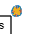

epc=10.^(-15:-1); % wektor mnożników (małych liczb) do skalowania zaburzeń
eelgc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie   
                        % błędu eliminacji bez wyboru elementu głównego
egzwc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie 
                        % błędu eliminacji z częściowym wyborem elementu głównego
eopMc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie 
                        % błędu wbudowanego operatora Ma
for k=1:length(epc)
    bm=b; % Skopiowanie wektora prawych stron do późniejszej modyfikacji
    bm(r)=bm(r)*(1+epc(k)); % Modyfikacja pojedynczego elementu prawej strony
    eelgc(k)=norm(elgauss2(A,bm)-x0)/norm(x0);
    egzwc(k)=norm(elgwegk(A,bm)-x0)/norm(x0);
    eopMc(k)=norm(A\bm-x0)/norm(x0);
end
loglog(epc,eelgc,'o-',epc,egzwc,'+-',epc,eopMc,'x-');hold on
legend('elgauss','elgwegk','A\\b');hold off

Z wykresu wynika, że metoda rozwiązywania równania nie wpływa na normę dla wybranej wartości zaburzenia multiplikatywnego.

Zmodyfikowano ten kod przykładowy tak, aby zbadać tylko eliminację Gaussa z częściowym wyborem elementu głównego, ale modyfikować układ równań na inne sposoby:

n=12;
[A,b,x0,bmax,bmin]=tstcndS(654321,n,1e5); % Wygenerowanie przykładowego 
                                            % układu równań 12x12 o 
                                            % liczbie uwarunkowania ok. 1e5
C=cond(A)

C =      1.000000002186461e+05

epc=10.^(-15:-1); % wektor mnożników (małych liczb) do skalowania zaburzeń

    1. Dodawać do wektora prawych stron pomnożony przez niewielką liczbę (epc) zwrócony przez `tstcndS `wektor $b_{max}$

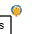

eelgc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie 
                        % błędu eliminacji bez wyboru elementu głównego
egzwc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji z częściowym wyborem elementu głównego
eopMc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu wbudowanego operatora Ma
for k=1:length(epc)
    bm=b; % Skopiowanie wektora prawych stron do późniejszej modyfikacji
    bm=bm + bmax * epc(k); % Modyfikacja pojedynczego elementu prawej strony
    eelgc(k)=norm(elgauss2(A,bm)-x0)/norm(x0);
    egzwc(k)=norm(elgwegk(A,bm)-x0)/norm(x0);
    eopMc(k)=norm(A\bm-x0)/norm(x0);
end
loglog(epc,eelgc,'o-',epc,egzwc,'+-',epc,eopMc,'x-');hold on
legend('elgauss','elgwegk','A\\b');hold off

    2. Dodawać do wektora prawych stron pomnożony przez niewielką liczbę (epc) zwrócony przez `tstcndS `wektor $b_{min}$

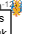

eelgc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji bez wyboru elementu głównego
egzwc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji z częściowym wyborem elementu głównego
eopMc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu wbudowanego operatora Ma
for k=1:length(epc)
    bm=b; % Skopiowanie wektora prawych stron do późniejszej modyfikacji
    bm=bm + bmin * epc(k); % Modyfikacja pojedynczego elementu prawej strony
    eelgc(k)=norm(elgauss2(A,bm)-x0)/norm(x0);
    egzwc(k)=norm(elgwegk(A,bm)-x0)/norm(x0);
    eopMc(k)=norm(A\bm-x0)/norm(x0);
end
loglog(epc,eelgc,'o-',epc,egzwc,'+-',epc,eopMc,'x-');hold on
legend('elgauss','elgwegk','A\\b');hold off

    3. Dodawać do wektora prawych stron pomnożony przez niewielką liczbę (epc) wektor losowy $v_{rnd}$

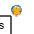

eelgc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji bez wyboru elementu głównego
egzwc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji z częściowym wyborem elementu głównego
eopMc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu wbudowanego operatora Ma
for k=1:length(epc)
    v=randn(n,1);v=v/norm(v);
    bm=b; % Skopiowanie wektora prawych stron do późniejszej modyfikacji
    bm=bm + v * epc(k); % Modyfikacja pojedynczego elementu prawej strony
    eelgc(k)=norm(elgauss2(A,bm)-x0)/norm(x0);
    egzwc(k)=norm(elgwegk(A,bm)-x0)/norm(x0);
    eopMc(k)=norm(A\bm-x0)/norm(x0);
end
loglog(epc,eelgc,'o-',epc,egzwc,'+-',epc,eopMc,'x-');hold on
legend('elgauss','elgwegk','A\\b');hold off

Wykresy zrobiono w skali logarytmicznej, używając jako odciętej względnej wartości zaburzenia, czyli $\frac{\left\|\varepsilon v\right\|}{\|b\|}$

gdzie $v$ jest jednym z wektorów $b_{min}, b_{max}, v_{rnd}$

Przeprowadzono podobny eksperyment, gdzie modyfikacji podlegał będzie nie wektor prawych stron, ale macierz $A$

1. Pomnożenie macierzy A pomnożony przez niewielką liczbę (epc) 

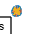

eelgc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji bez wyboru elementu głównego
egzwc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie błędu
                        % eliminacji z częściowym wyborem elementu głównego
eopMc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu wbudowanego operatora Ma
for k=1:length(epc)
    Am=A; % Skopiowanie wektora prawych stron do późniejszej modyfikacji
    Am=Am * (1 + epc(k)); % Modyfikacja pojedynczego elementu prawej strony
    eelgc(k)=norm(elgauss2(Am,b)-x0)/norm(x0);
    egzwc(k)=norm(elgwegk(Am,b)-x0)/norm(x0);
    eopMc(k)=norm(Am\b-x0)/norm(x0);
end
loglog(epc,eelgc,'o-',epc,egzwc,'+-',epc,eopMc,'x-');hold on
legend('elgauss','elgwegk','A\\b');hold off

    2. Dodawać do macierzy A pomnożony przez niewielką liczbę (epc) macierz losową $V_{rnd}$ 

eelgc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji bez wyboru elementu głównego
egzwc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu eliminacji z częściowym wyborem elementu głównego
eopMc=zeros(size(epc)); % Zarezerwowanie tablicy na zapisanie
                        % błędu wbudowanego operatora Ma
for k=1:length(epc)
    V=randn(n,n);V=V/norm(V);
    Am=A; % Skopiowanie wektora prawych stron do późniejszej modyfikacji
    Am=Am + V * epc(k); % Modyfikacja pojedynczego elementu prawej strony
    eelgc(k)=norm(elgauss2(Am,b)-x0)/norm(x0);
    egzwc(k)=norm(elgwegk(Am,b)-x0)/norm(x0);
    eopMc(k)=norm(Am\b-x0)/norm(x0);
end
loglog(epc,eelgc,'o-',epc,egzwc,'+-',epc,eopMc,'x-');hold on
legend('elgauss','elgwegk','A\\b');hold off

Wykresy przedstawiają, że niezależnie od rodzaju zaburzenia, metoda eliminacji Gaussa bez wyboru elementu głównego jest gorsza lub równa, ze względu na błąd, metodzie z częściowym wyborem elementu głównego. Wykresy również pokazują zbieżność błędów dla metody eliminacji z częściowym wyboruem elementu głównego oraz metody, z której korzysta wbudowany operator Matlab-a.

Wykorzystane w ćwiczeniu funkcje:

function [x, L, U] = elgauss(A, b)
[n,m]=size(A); % Odczytanie wymiarów macierzy A
[nb,~]=size(b); % Odczytanie liczby wierszy prawej strony
if n~=m, error("Macierz A musi być kwadratowa"); end % Test czy macierz jest kwadratowa
% Test kompatybilności prawej strony
if n~=nb, error("Macierz A i b muszą mieć tyle samo wierszy"); end 
AB=[A,b]; % "Zblokowanie" macierzy układu i prawych stron
L=eye(n);
for k=1:n-1 
    L(k+1:end,k)=AB(k+1:end,k)/AB(k,k);
    AB(k+1:end,:)=AB(k+1:end,:)-L(k+1:end,k)*AB(k,:);
end
x=zeros(size(b)); % Zaincjowanie zmiennej wyjściowej
x(n,:)=AB(n,n+1:end)/AB(n,n); % Obliczenie ostatniej (ostatnich) niewiadomych
for k=n-1:-1:1
    x(k,:)=(AB(k,n+1:end)-AB(k,k+1:n)*x(k+1:end,:))/AB(k,k); % Podstawienie wstecz
end
U=triu(AB(1:end,1:n)); % Wydzielenie czynnika trójkątnego górnego
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x, U, L] = elgauss2(A, b)
[n,m]=size(A); % Odczytanie wymiarów macierzy A
[nb,~]=size(b); % Odczytanie liczby wierszy prawej strony
% Test czy macierz jest kwadratowa
if n~=m, error("Macierz A musi być kwadratowa"); end
% Test kompatybilności prawej strony
if n~=nb, error("Macierz A i b muszą mieć tyle samo wierszy"); end 
AB=[A,b]; % "Zblokowanie" macierzy układu i prawych stron
for k=1:n-1 
    AB(k+1:end,k)=AB(k+1:end,k)/AB(k,k);
    AB(k+1:end,k+1:end)=AB(k+1:end,k+1:end)-AB(k+1:end,k)*AB(k,k+1:end);
end
x=nan(size(b)); % Zaincjowanie zmiennej wyjściowej
x(n,:)=AB(n,n+1:end)/AB(n,n); % Obliczenie ostatniej (ostatnich) niewiadomych
for k=n-1:-1:1
    x(k,:)=(AB(k,n+1:end)-AB(k,k+1:n)*x(k+1:end,:))/AB(k,k); % Podstawienie wstecz
end

U=triu(AB(1:end,1:n)); % Wydzielenie czynnika trójkątnego górnego
L=tril(AB(1:end,1:n),-1)+eye(n); % Wydzielenie czynnika trójkątnego dolnego
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x, U, L, P] = elgwegk(A, b)
[n,m]=size(A); % Odczytanie wymiarów macierzy A
[nb,~]=size(b); % Odczytanie liczby wierszy prawej strony
% Test czy macierz jest kwadratowa
if n~=m, error("Macierz A musi być kwadratowa"); end 
% Test kompatybilności prawej strony
if n~=nb, error("Macierz A i b muszą mieć tyle samo wierszy"); end
AB=[A,b]; % "Zblokowanie" macierzy układu i prawych stron
P=zeros(n,n); % wektor zapamiętujący zamiany wierszów macierzy
for k=1:n-1 
    [~,idx]=max(abs(AB(k:end,k)));
    if idx > 1
        AB([k,k+idx-1],:)=AB([k+idx-1,k],:);
        P(k,k+idx-1) = 1;
    end
    AB(k+1:end,k)=AB(k+1:end,k)/AB(k,k);
    AB(k+1:end,k+1:end)=AB(k+1:end,k+1:end)-AB(k+1:end,k)*AB(k,k+1:end);
end
x=nan(size(b)); % Zaincjowanie zmiennej wyjściowej
x(n,:)=AB(n,n+1:end)/AB(n,n); % Obliczenie ostatniej (ostatnich) niewiadomych
for k=n-1:-1:1
    x(k,:)=(AB(k,n+1:end)-AB(k,k+1:n)*x(k+1:end,:))/AB(k,k); % Podstawienie wstecz
end
U=triu(AB(1:end,1:n)); % Wydzielenie czynnika trójkątnego górnego
L=tril(AB(1:end,1:n),-1)+eye(n); % Wydzielenie czynnika trójkątnego dolnego
end